% Fs = 40000; %Humans can hear up to about 20,000 Hz.
% nBits = 16;
% 
% % Create two separate objects for two separate hardware IDs
% rec1 = audiorecorder(Fs, nBits, 1, 1); % Device ID 1
% rec2 = audiorecorder(Fs, nBits, 1, 0); % Device ID 2 (Your second USB mic)
% 
% % Start both "simultaneously"
% beep;
% pause(1)
% disp("recording...")
% 
% record(rec1); 
% record(rec2); 
% 
% % Keep recording for 2 seconds
% pause(5); 
% 
% % Stop both
% stop(rec1);
% stop(rec2);
% pause(1)
% beep;
% disp("end...")

clc; clear; close all;

% Load CSV
data = readmatrix('mic_data_100cm.csv');

mic1 = data(:,1);
mic2 = data(:,2);

Fs = 40000; %Humans can hear up to about 20,000 Hz.
nBits = 16;

% % Extract and align
% mic1 = getaudiodata(rec1);
% mic2 = getaudiodata(rec2);

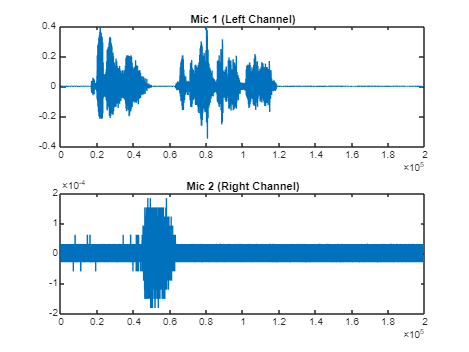


% Check if they are different
figure;
subplot(2,1,1); plot(mic1); title('Mic 1 (Left Channel)');
subplot(2,1,2); plot(mic2); title('Mic 2 (Right Channel)');

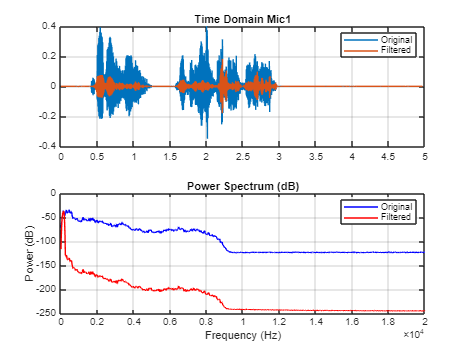

Ts = 1/Fs;               % Sampling period
N = length(mic1);        % Number of samples
% Find the shorter length
minLength = min(length(mic1), length(mic2));

% Crop both to the same size
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);

% Now you can create ONE time vector for both
t = (0:minLength-1) * (1/Fs);

% Lowpass
mic1_f = bandpass(mic1, [80 150], Fs);
mic2_f = bandpass(mic2, [80 150], Fs);

% Mic 1
figure;
subplot(2,1,1);
plot(t, mic1); hold on;
plot(t, mic1_f);
title('Time Domain Mic1');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on;
plot(ff1, 10*log10(pf1), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

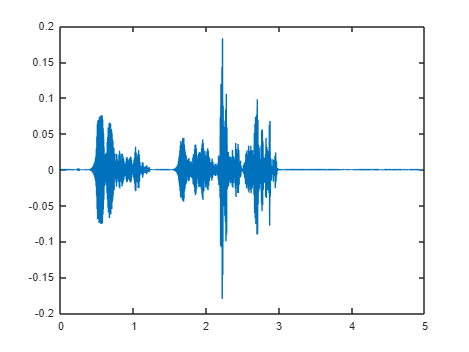

clf
plot(t,mic1_f)

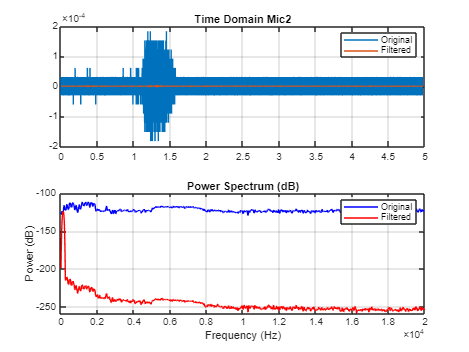


% Mic 2
figure;
subplot(2,1,1);
plot(t, mic2); hold on;
plot(t, mic2_f);
title('Time Domain Mic2');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), '-b'); hold on;
plot(ff2, 10*log10(pf2), '-r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

clf;

plot(t,mic1_f);

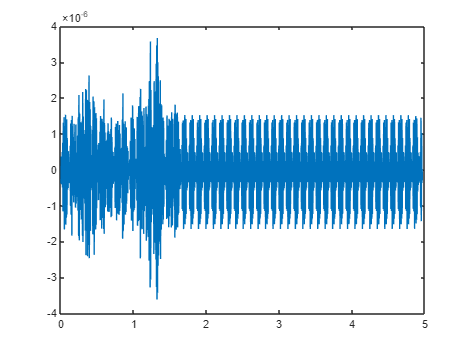

plot(t,mic2_f);

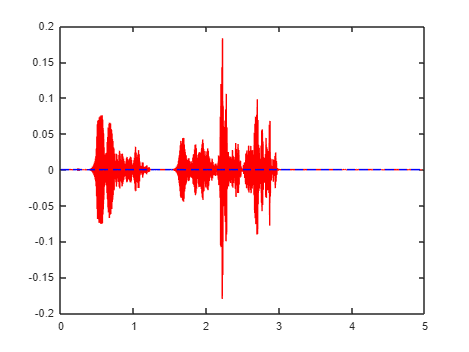



figure;
plot(t,mic1_f,"r")
hold on
plot(t,mic2_f,"--b")
hold off


%% --- TDOA Estimation
mic_spacing_m = 1.5;       % Set your actual mic spacing in meters
v_sound = 343;             % m/s
max_delay_s = mic_spacing_m / v_sound;   % e.g. ~0.003 s
max_lag_samples = round(max_delay_s * Fs) ;  
% Normalized cross-correlation (GCC-style, time domain)
[xc12, lags12] = xcorr(mic1_f, mic2_f, max_lag_samples, 'normalized');

[~, idx12] = max(abs(xc12));
lag12       = lags12(idx12);
delay12     = lag12 / Fs;

fprintf('Lag:   %d samples\n', lag12);

Lag:   105 samples


fprintf('Delay: %.6f s  (%.4f ms)\n', delay12, delay12*1000);

Delay: 0.002625 s  (2.6250 ms)


v = 343; 
distance_diff = delay12 * v % Difference in distance to the source (meters)

distance_diff = 0.9004

writematrix([mic1, mic2], 'mic_data_hamcm.csv');